## World Bank Data Harvesting Example

In this example, we download GDP data from the World Bank, plot it on a world map and save the collected data in Nuvolos.

### Prerequisites

This example uses the 'Worldbank API Acces' and the 'borders' community-developed add-ons, they can be installed from the Add-Ons Manager.

clearvars
if isfile('/dhlib/Toolboxes/borders_v3.1.2/borders/borders.m')
     % Addon is installed
else
    [mfp,mfname,ext] = fileparts(matlab.desktop.editor.getActiveFilename);
    unzip('/files/examples/data/worldbank_upload/MATLAB/addon/borders_v3.1.2.zip','/dhlib/Toolboxes/borders_v3.1.2/');
    copyfile(fullfile(mfp,'addon/borders.m'),'/dhlib/Toolboxes/borders_v3.1.2/borders/borders.m');
end
if isfile('/dhlib/Toolboxes/Worldbank API Access/WorldBank API Access/@wb/importdataset.m')
     % Addon is installed
else
    [mfp,mfname,ext] = fileparts(matlab.desktop.editor.getActiveFilename);
    unzip('/files/examples/data/worldbank_upload/MATLAB/addon/WorldBank API Access.zip','/dhlib/Toolboxes/Worldbank API Access/');
    copyfile(fullfile(mfp,'addon/importdataset.m'),'/dhlib/Toolboxes/Worldbank API Access/WorldBank API Access/@wb/importdataset.m');
end

addpath('/dhlib/Toolboxes/borders_v3.1.2/');
addpath('/dhlib/Toolboxes/borders_v3.1.2/borders/');
addpath('/dhlib/Toolboxes/Worldbank API Access/');
addpath('/dhlib/Toolboxes/Worldbank API Access/WorldBank API Access');
addpath('/dhlib/Toolboxes/Worldbank API Access/WorldBank API Access/publish');

### Retrieving GDP data

Foreign direct investment GDP data is retrieved from the World Bank Data API using the Worldbank API Access add-on:

conn = wb();

Country data are being downloaded and then imported... Done. 
Topic data are being downloaded and then imported... Done. 
Region data are being downloaded and then imported... Done. 
Income level data are being downloaded and then imported... Done. 
Lending type data are being downloaded and then imported... Done. 
Indicator data are being downloaded and then imported... Done. 
Source data are being downloaded and then imported... Done. 
Concept data are being downloaded and then imported... Done. 
Concept variables data are being downloaded and then imported... 

Done. 


request = header(conn, 'country','all',...
    'indicator','BX.KLT.DINV.WD.GD.ZS',...
    'date','2000:2010');
raw_data1 = send(conn,request);
request = header(conn, 'country','all',...
    'indicator','BX.KLT.DINV.WD.GD.ZS',...
    'date','2011:2020');
raw_data2 = send(conn,request);


Once the data has been retrieved, it has to be formed into a table:

s1 = size(raw_data1{2,1});
s2 = size(raw_data2{2,1});
row_count = s1(1) + s2(1);
gdp_data = cell(row_count, 4);
for n=1:s1(1)
    gdp_data{n,1} = raw_data1{2,1}(n).country.value;
    gdp_data{n,2} = str2double(raw_data1{2,1}(n).date);
    gdp_data{n,3} = raw_data1{2,1}(n).value;
    gdp_data{n,4} = raw_data1{2,1}(n).countryiso3code;
end
for n=1:s2(1)
    gdp_data{n + s1(1),1} = raw_data2{2,1}(n).country.value;
    gdp_data{n + s1(1),2} = str2double(raw_data2{2,1}(n).date);
    gdp_data{n + s1(1),3} = raw_data2{2,1}(n).value;
    gdp_data{n + s1(1),4} = raw_data2{2,1}(n).countryiso3code;
end

### Staging data to a table

Then we convert the cell to a table and save it to Nuvolos:

T = cell2table(gdp_data,"VariableNames",{'country' 'year' 'foreign_direct_investment' 'iso3'});
nuvolos_conn = get_connection();
coltypes = ["varchar(255)" "int" "decimal(24,8)" "char(3)"];
execute(nuvolos_conn,'DROP TABLE IF EXISTS fdi_gdp_pct_matlab;')
sqlwrite(nuvolos_conn,'FDI_GDP_PCT_MATLAB',T, 'ColumnType', coltypes);

### Plotting data

Next, we select data from the database table and plot it on a world map. We use 'borders' community-sourced add-on for plotting, it doesn not require a Mapping Toolbox license.

The add-on uses the World Borders Dataset for country borders data: http://thematicmapping.org/downloads/world_borders.php

Due to the slight differences in country names used by the World Bank and the 'borders' add-on, we need to match the names from the two datasets using ISO3 country codes:

T_iso = readtable('/files/examples/data/worldbank_upload/MATLAB/input/countries.csv');
coltypes2 = ["char(2)" "char(2)" "char(3)" "int" "varchar(50)" "int" "int" "int" "int" "decimal(18,4)" "decimal(18,4)"];
execute(nuvolos_conn,'DROP TABLE IF EXISTS countries;')
sqlwrite(nuvolos_conn,'COUNTRIES',T_iso, 'ColumnType', coltypes2);
T2018 = select(nuvolos_conn,['SELECT c.name, f.* ' ...
    'FROM fdi_gdp_pct_matlab AS f ' ...
    'INNER JOIN countries AS c ' ...
    'ON f.iso3=c.iso3 ' ...
    'WHERE f.year=2018;']);
fillmissing(T2018.FOREIGN_DIRECT_INVESTMENT,"constant",0);

Once we have the country names and foreign direct investment values, we can plot them using the 'borders' function:

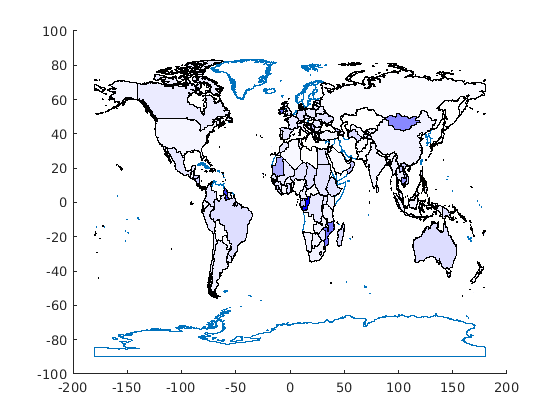

country = 1×1 cell array
    {'Zimbabwe'}


country = 1×1 cell array
    {'Zambia'}


country = 1×1 cell array
    {'Yemen'}


Country not found: Yemen

country = 1×1 cell array
    {'Palestine'}


country = 1×1 cell array
    {'United States Virgin Islands'}


Country not found: United States Virgin Islands

country = 1×1 cell array
    {'Viet Nam'}


country = 1×1 cell array
    {'Venezuela'}


Country not found: Venezuela

country = 1×1 cell array
    {'Vanuatu'}


country = 1×1 cell array
    {'Uzbekistan'}


country = 1×1 cell array
    {'Uruguay'}


country = 1×1 cell array
    {'United States'}


country = 1×1 cell array
    {'United Kingdom'}


country = 1×1 cell array
    {'United Arab Emirates'}


country = 1×1 cell array
    {'Ukraine'}


country = 1×1 cell array
    {'Uganda'}


country = 1×1 cell array
    {'Tuvalu'}


country = 1×1 cell array
    {'Turks and Caicos Islands'}


country = 1×1 cell array
    {'Turkmenistan'}


country = 1×1 cell array
    {'Turkey'}


country = 1×1 cell array
    {'Tunisia'}


country = 1×1 cell array
    {'Trinidad and Tobago'}


Country not found: Trinidad and Tobago

country = 1×1 cell array
    {'Tonga'}


country = 1×1 cell array
    {'Togo'}


Country not found: Togo

country = 1×1 cell array
    {'Timor-Leste'}


country = 1×1 cell array
    {'Thailand'}


country = 1×1 cell array
    {'United Republic of Tanzania'}


country = 1×1 cell array
    {'Tajikistan'}


country = 1×1 cell array
    {'Syrian Arab Republic'}


Country not found: Syrian Arab Republic

country = 1×1 cell array
    {'Switzerland'}


Country not found: Switzerland

country = 1×1 cell array
    {'Sweden'}


Country not found: Sweden

country = 1×1 cell array
    {'Suriname'}


country = 1×1 cell array
    {'Sudan'}


country = 1×1 cell array
    {'Saint Vincent and the Grenadines'}


country = 1×1 cell array
    {'Saint Martin'}


Country not found: Saint Martin

country = 1×1 cell array
    {'Saint Lucia'}


country = 1×1 cell array
    {'Saint Kitts and Nevis'}


country = 1×1 cell array
    {'Sri Lanka'}


country = 1×1 cell array
    {'Spain'}


country = 1×1 cell array
    {'South Africa'}


country = 1×1 cell array
    {'Somalia'}


Country not found: Somalia

country = 1×1 cell array
    {'Solomon Islands'}


country = 1×1 cell array
    {'Slovenia'}


country = 1×1 cell array
    {'Slovakia'}


country = 1×1 cell array
    {'Singapore'}


country = 1×1 cell array
    {'Sierra Leone'}


country = 1×1 cell array
    {'Seychelles'}


country = 1×1 cell array
    {'Serbia'}


country = 1×1 cell array
    {'Senegal'}


country = 1×1 cell array
    {'Saudi Arabia'}


country = 1×1 cell array
    {'Sao Tome and Principe'}


country = 1×1 cell array
    {'San Marino'}


Country not found: San Marino

country = 1×1 cell array
    {'Samoa'}


country = 1×1 cell array
    {'Rwanda'}


country = 1×1 cell array
    {'Russia'}


country = 1×1 cell array
    {'Romania'}


country = 1×1 cell array
    {'Qatar'}


Country not found: Qatar

country = 1×1 cell array
    {'Puerto Rico'}


Country not found: Puerto Rico

country = 1×1 cell array
    {'Portugal'}


country = 1×1 cell array
    {'Poland'}


country = 1×1 cell array
    {'Philippines'}


country = 1×1 cell array
    {'Peru'}


country = 1×1 cell array
    {'Paraguay'}


country = 1×1 cell array
    {'Papua New Guinea'}


country = 1×1 cell array
    {'Panama'}


country = 1×1 cell array
    {'Palau'}


country = 1×1 cell array
    {'Pakistan'}


country = 1×1 cell array
    {'Oman'}


country = 1×1 cell array
    {'Norway'}


Country not found: Norway

country = 1×1 cell array
    {'Northern Mariana Islands'}


Country not found: Northern Mariana Islands

country = 1×1 cell array
    {'The former Yugoslav Republic of Macedonia'}


country = 1×1 cell array
    {'Nigeria'}


country = 1×1 cell array
    {'Niger'}


country = 1×1 cell array
    {'Nicaragua'}


country = 1×1 cell array
    {'New Zealand'}


country = 1×1 cell array
    {'New Caledonia'}


Country not found: New Caledonia

country = 1×1 cell array
    {'Netherlands'}


Country not found: Netherlands

country = 1×1 cell array
    {'Nepal'}


country = 1×1 cell array
    {'Nauru'}


country = 1×1 cell array
    {'Namibia'}


country = 1×1 cell array
    {'Burma'}


country = 1×1 cell array
    {'Mozambique'}


country = 1×1 cell array
    {'Morocco'}


country = 1×1 cell array
    {'Montenegro'}


country = 1×1 cell array
    {'Mongolia'}


country = 1×1 cell array
    {'Monaco'}


Country not found: Monaco

country = 1×1 cell array
    {'Republic of Moldova'}


country = 1×1 cell array
    {'Micronesia, Federated States of                   '}


String 'Micronesia, Federated States of                   ' not found. Did you mean...
    {'Micronesia, Federated States of'}
    {'Michigan'                       }



country = 1×1 cell array
    {'Mexico'}


country = 1×1 cell array
    {'Mauritius'}


country = 1×1 cell array
    {'Mauritania'}


country = 1×1 cell array
    {'Marshall Islands'}


country = 1×1 cell array
    {'Malta'}


country = 1×1 cell array
    {'Mali'}


country = 1×1 cell array
    {'Maldives'}


country = 1×1 cell array
    {'Malaysia'}


country = 1×1 cell array
    {'Malawi'}


country = 1×1 cell array
    {'Madagascar'}


country = 1×1 cell array
    {'Macau'}


country = 1×1 cell array
    {'Luxembourg'}


Country not found: Luxembourg

country = 1×1 cell array
    {'Lithuania'}


country = 1×1 cell array
    {'Liechtenstein'}


Country not found: Liechtenstein

country = 1×1 cell array
    {'Libyan Arab Jamahiriya'}


country = 1×1 cell array
    {'Liberia'}


country = 1×1 cell array
    {'Lesotho'}


country = 1×1 cell array
    {'Lebanon'}


country = 1×1 cell array
    {'Latvia'}


country = 1×1 cell array
    {'Lao People's Democratic Republic'}


country = 1×1 cell array
    {'Kyrgyzstan'}


country = 1×1 cell array
    {'Kuwait'}


Country not found: Kuwait

country = 1×1 cell array
    {'Korea, Republic of                                '}


String 'Korea, Republic of                                ' not found. Did you mean...
    {'Korea, Democratic People's Republic of'}
    {'Korea, Republic of'                    }



country = 1×1 cell array
    {'Korea, Democratic People's Republic of            '}


String 'Korea, Democratic People's Republic of            ' not found. Did you mean...
    {'Korea, Democratic People's Republic of'}
    {'Korea, Republic of'                    }



country = 1×1 cell array
    {'Kiribati'}


Country not found: Kiribati

country = 1×1 cell array
    {'Kenya'}


country = 1×1 cell array
    {'Kazakhstan'}


country = 1×1 cell array
    {'Jordan'}


country = 1×1 cell array
    {'Japan'}


country = 1×1 cell array
    {'Jamaica'}


country = 1×1 cell array
    {'Italy'}


country = 1×1 cell array
    {'Israel'}


country = 1×1 cell array
    {'Isle of Man'}


Country not found: Isle of Man

country = 1×1 cell array
    {'Ireland'}


country = 1×1 cell array
    {'Iraq'}


Country not found: Iraq

country = 1×1 cell array
    {'Iran (Islamic Republic of)'}


String 'Iran (Islamic Republic of)' not found. Did you mean...
    {'Central African Republic'}
    {'Dominican Republic'      }
    {'Ireland'                 }
    {'Iran Islamic Republic of'}
    {'Iraq'                    }
    {'Syrian Arab Republic'    }
    {'District of Columbia'    }



country = 1×1 cell array
    {'Indonesia'}


country = 1×1 cell array
    {'India'}


country = 1×1 cell array
    {'Iceland'}


Country not found: Iceland

country = 1×1 cell array
    {'Hungary'}


Country not found: Hungary

country = 1×1 cell array
    {'Hong Kong'}


country = 1×1 cell array
    {'Honduras'}


country = 1×1 cell array
    {'Haiti'}


country = 1×1 cell array
    {'Guyana'}


country = 1×1 cell array
    {'Guinea-Bissau'}


country = 1×1 cell array
    {'Guinea'}


country = 1×1 cell array
    {'Guatemala'}


country = 1×1 cell array
    {'Guam'}


Country not found: Guam

country = 1×1 cell array
    {'Grenada'}


country = 1×1 cell array
    {'Greenland'}


Country not found: Greenland

country = 1×1 cell array
    {'Greece'}


country = 1×1 cell array
    {'Gibraltar'}


Country not found: Gibraltar

country = 1×1 cell array
    {'Ghana'}


country = 1×1 cell array
    {'Germany'}


country = 1×1 cell array
    {'Georgia'}


country = 1×1 cell array
    {'Gambia'}


country = 1×1 cell array
    {'Gabon'}


country = 1×1 cell array
    {'French Polynesia'}


Country not found: French Polynesia

country = 1×1 cell array
    {'France'}


country = 1×1 cell array
    {'Finland'}


Country not found: Finland

country = 1×1 cell array
    {'Fiji'}


country = 1×1 cell array
    {'Faroe Islands'}


Country not found: Faroe Islands

country = 1×1 cell array
    {'Ethiopia'}


country = 1×1 cell array
    {'Swaziland'}


country = 1×1 cell array
    {'Estonia'}


country = 1×1 cell array
    {'Eritrea'}


Country not found: Eritrea

country = 1×1 cell array
    {'Equatorial Guinea'}


country = 1×1 cell array
    {'El Salvador'}


country = 1×1 cell array
    {'Egypt'}


country = 1×1 cell array
    {'Ecuador'}


country = 1×1 cell array
    {'Dominican Republic'}


country = 1×1 cell array
    {'Dominica'}


country = 1×1 cell array
    {'Djibouti'}


country = 1×1 cell array
    {'Denmark'}


country = 1×1 cell array
    {'Czech Republic'}


country = 1×1 cell array
    {'Cyprus'}


Country not found: Cyprus

country = 1×1 cell array
    {'Cuba'}


Country not found: Cuba

country = 1×1 cell array
    {'Croatia'}


country = 1×1 cell array
    {'Cote d'Ivoire'}


country = 1×1 cell array
    {'Costa Rica'}


country = 1×1 cell array
    {'Congo'}


country = 1×1 cell array
    {'Democratic Republic of the Congo'}


country = 1×1 cell array
    {'Comoros'}


country = 1×1 cell array
    {'Colombia'}


country = 1×1 cell array
    {'China'}


country = 1×1 cell array
    {'Chile'}


country = 1×1 cell array
    {'Chad'}


country = 1×1 cell array
    {'Central African Republic'}


country = 1×1 cell array
    {'Cayman Islands'}


country = 1×1 cell array
    {'Canada'}


country = 1×1 cell array
    {'Cameroon'}


country = 1×1 cell array
    {'Cambodia'}


country = 1×1 cell array
    {'Cape Verde'}


country = 1×1 cell array
    {'Burundi'}


country = 1×1 cell array
    {'Burkina Faso'}


country = 1×1 cell array
    {'Bulgaria'}


country = 1×1 cell array
    {'Brunei Darussalam'}


country = 1×1 cell array
    {'British Virgin Islands'}


Country not found: British Virgin Islands

country = 1×1 cell array
    {'Brazil'}


country = 1×1 cell array
    {'Botswana'}


country = 1×1 cell array
    {'Bosnia and Herzegovina'}


country = 1×1 cell array
    {'Bolivia'}


country = 1×1 cell array
    {'Bhutan'}


country = 1×1 cell array
    {'Bermuda'}


country = 1×1 cell array
    {'Benin'}


country = 1×1 cell array
    {'Belize'}


country = 1×1 cell array
    {'Belgium'}


Country not found: Belgium

country = 1×1 cell array
    {'Belarus'}


country = 1×1 cell array
    {'Barbados'}


country = 1×1 cell array
    {'Bangladesh'}


country = 1×1 cell array
    {'Bahrain'}


country = 1×1 cell array
    {'Bahamas'}


country = 1×1 cell array
    {'Azerbaijan'}


country = 1×1 cell array
    {'Austria'}


Country not found: Austria

country = 1×1 cell array
    {'Australia'}


country = 1×1 cell array
    {'Aruba'}


Country not found: Aruba

country = 1×1 cell array
    {'Armenia'}


country = 1×1 cell array
    {'Argentina'}


country = 1×1 cell array
    {'Antigua and Barbuda'}


country = 1×1 cell array
    {'Angola'}


Country not found: Angola

country = 1×1 cell array
    {'Andorra'}


Country not found: Andorra

country = 1×1 cell array
    {'American Samoa'}


Country not found: American Samoa

country = 1×1 cell array
    {'Algeria'}


country = 1×1 cell array
    {'Albania'}


country = 1×1 cell array
    {'Afghanistan'}


mapping_toolbox_installed = contains(struct2array(ver), 'Mapping Toolbox');
if mapping_toolbox_installed
    bordersm
else
    borders
end
for i=1:height(T2018)
    try
        alpha = T2018{i,"FOREIGN_DIRECT_INVESTMENT"} / max(T2018.FOREIGN_DIRECT_INVESTMENT);
        country = T2018{i, "NAME"}
        if mapping_toolbox_installed
            bordersm(country{1},'facecolor',[0 0 1], 'facealpha', alpha);
        else    
            borders(country{1},'facecolor',[0 0 1], 'facealpha', alpha);
        end
    catch
        fprintf("Country not found: %s",country{1});
    end
end